# Chapter 2: The Abelson's models

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

## 2.1 Abelson's models of opinion dynamics

Abelson proposed a continuous-time counterpart of the French-DeGroot model [M1.1](matlab:open('./ch01_fdg.mlx')). The derivation can be found inside section 4.1 in the [following paper](matlab:open('../1-s2.0-S1367578817300172-mainext.pdf')).

The continous time linear dynamics is 

                                                            (M2.1)$\dot x_i(t) = \sum _{j \ne i} a_{ij}(x_j(t)-x_i(t)), \ i = 1, \dots, n$

$A = (a_{ij})$ is a non-negative matrix of influence weights. 

A more general nonlinear  mechanism of opinion evolution is

                                                            (M2.2)$\dot x_i(t) = \sum _{j \ne i} a_{ij}g(x_i,x_j)(x_j(t)-x_i(t)), \ \forall i$

$g: \mathbb R \times \mathbb R \rightarrow (0,1]$ is a coupling function describing the complex mechanism of opinion assimilation.

We mainly deal with the **linear Abelson model** M2.1 whose equivalent matrix form is

                                                                        (M2.3)$\dot x(t) = -L[A]x(t)
$

where $L[A]$ is the Laplacian Matrix.

## 2.2 Convergence and Consensus criteria

Note that Corollary 0.X (da inserire link), applied to the M-matrix $L[A]$ and $\lambda_0=0$, implies that all Jordan blocks, corresponding to the eigenvalue $\lambda_0=0$, are trivial and for any other eigenvalue $\lambda$ of the Laplacian the real part is greater than zero. Thus M2.3 is Lyapunov stable (yet not asymptotically stable) and, unlike FDG model, is always convergent.

**Corollary 2.1** For any nonnegative matrix $A$ the limit $P^\infty = \lim_{t \rightarrow \infty} e^{-L[A]t}$ exists, and thur the vectors of opinions in M2.3 converges $x(t) \rightarrow x^\infty = P^\infty x(0)$ for $t \rightarrow \infty$.

The matrix $P^\infty$ is a projection operator onto the Laplacian's null space, $\ker L[A] = \{v : L[A]v = 0\},$and is therefore closely related to the structure of the graph. Similarly to the discrete-time model M1.1 , system M2.3 reaches consensus if, for every initial condition $x(0)$, $x_1^\infty = \cdots = x_n^\infty$. Hence, consensus requires $\mathbb{Im} P^\infty \subseteq span\{\mathbb{1}_n\},$ so that $P^\infty = \mathbb{1}_n p_\infty^\top$ for some $p_\infty \in \mathbb{R}^n$ . Since $\mathbb{1}_n$ is an equilibrium point, $P\mathbb{1}_n = \mathbb{1}_n,$and consequently $p_\infty^\top \mathbb{1}_n = 1.$Moreover, because $P$ commutes with $L[A]$, $p_\infty^\top L[A] = 0.$ Since $L[A]$ has a nonnegative left eigenvector $p$ associated with the eigenvalue $0$, and $\dim \  \ker L[A] = 1$ , it follows that $p_\infty = cp,  c>0.$ Thus, by combining these properties, one obtains the following consensus criterion.

**Theorem 2.1 **The lineare Abelson model M2.3 reaches consensu $\iff$ $\mathcal G[A]$ is quasi-strongly connected. In this case, the opinions converge to the limit $\lim_{t\rightarrow \infty}x_1(t) = \dots = \lim_{t\rightarrow \infty} x_n(t) = p_\infty^Tx(0)$ where $p^\infty \in \mathbb R$ is the nonnegative vector, uniquely defined by the equations $p_\infty^TL[A]=0$ and $p_\infty^T \mathbb 1_n = 1$.

The vector $p_\infty$ may be treated as a vector of the agent's social powers, or a centrality measure on the nodes of $\mathcal G[A]$.

Model  M2.3 arises as a "limit" of the FDG model as the time between consecutive opinion updates becomes negligibly small. The inverse operation of discretization transforms  M2.3 into the FDG model.

**Lemma 2.1 **For any nonnegative matrix $A$ and $\tau >0$ the matrix $W_\tau = e^{-\tau L[A]}$ is stochastic, and thus $P^{\infty} = \lim_{\tau \rightarrow \infty} W_\tau$ from **Corollary 2.1** is stochastic. The matrices $W_\tau$ have positive diagonal entries.

Such lemma imples that vectors $\tilde x(k) = x(\tau k)$ satisfy a special FDG model with $W = W_\tau$ and allows to derive Theorem 2.1 from Corollary 1.1.

## 2.3 The community cleavage problem

The informal formulation, stated by Abelson, was: *"Since universal ultimate agreement is an ubiquitous outcome of a very broad class of mathematical models, we are naturally led to inquire what on earth one must assue in order to generate bimodal outcome of community cleavage studies."*

In other words, the reasons for social cleavage, that is, persistent disagreement among the agents' opinions (eg. clustering) are to be identified. 

One of the reason for opinion cluestring is the presence of stubborn agents, whose opinions are invariant. In models M2.1 and M2.2, agent $i$ is stubborn $\iff$ $a_{ij} = 0 \forall i$, corresponding thus to a source node of the graph $\mathcal G [A]$.

## 2.4 Examples

The structure of Chapter 1 applied to xdot = -L x. The agent count and the initial condition are those of Chapter 1, so the two chapters can be read against each other.

N  = 6;
x0 = [3; -1; 5; 0; 2; -2];      % the initial condition used throughout Chapter 1
t  = linspace(0, 15, 400);      % continuous time

fprintf('N = %d, mean x0 = %.4f\n', N, mean(x0));

N = 6, mean x0 = 1.1667


## 2.4.1 The periodicity obstruction disappears

The directed cycle and the bidirectional star are the two topologies of Chapter 1 that never converge. Under the Abelson model both do.

A = ring_graph(N)

A =      0     0     0     0     0     1
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0


D = diag(sum(A, 2))

D =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


L = laplacian(A)

L =      1     0     0     0     0    -1
    -1     1     0     0     0     0
     0    -1     1     0     0     0
     0     0    -1     1     0     0
     0     0     0    -1     1     0
     0     0     0     0    -1     1



s = laplacian_report(A, 'A (directed cycle)');

A (directed cycle)   (6 agents, continuous time)
  strengths (row sums of A): [1 1 1 1 1 1]
  in-strengths (col sums)  : [1 1 1 1 1 1]   weight-balanced: yes
  strong components : 1   closed: 1
  rooted: yes   ->  converges to CONSENSUS at p'x(0)
  eigenvalue 0 of L: multiplicity 1   spectral gap: 0.5000


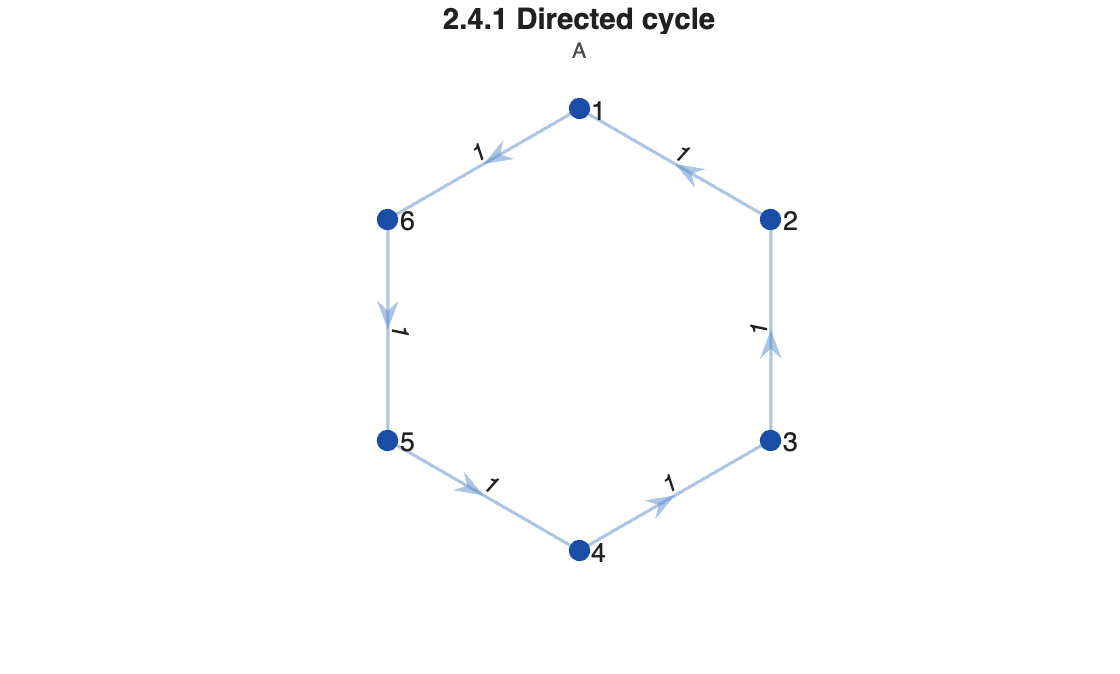

figure; plot_graph(A, [], 'Title','2.4.1 Directed cycle', 'Subtitle','A')

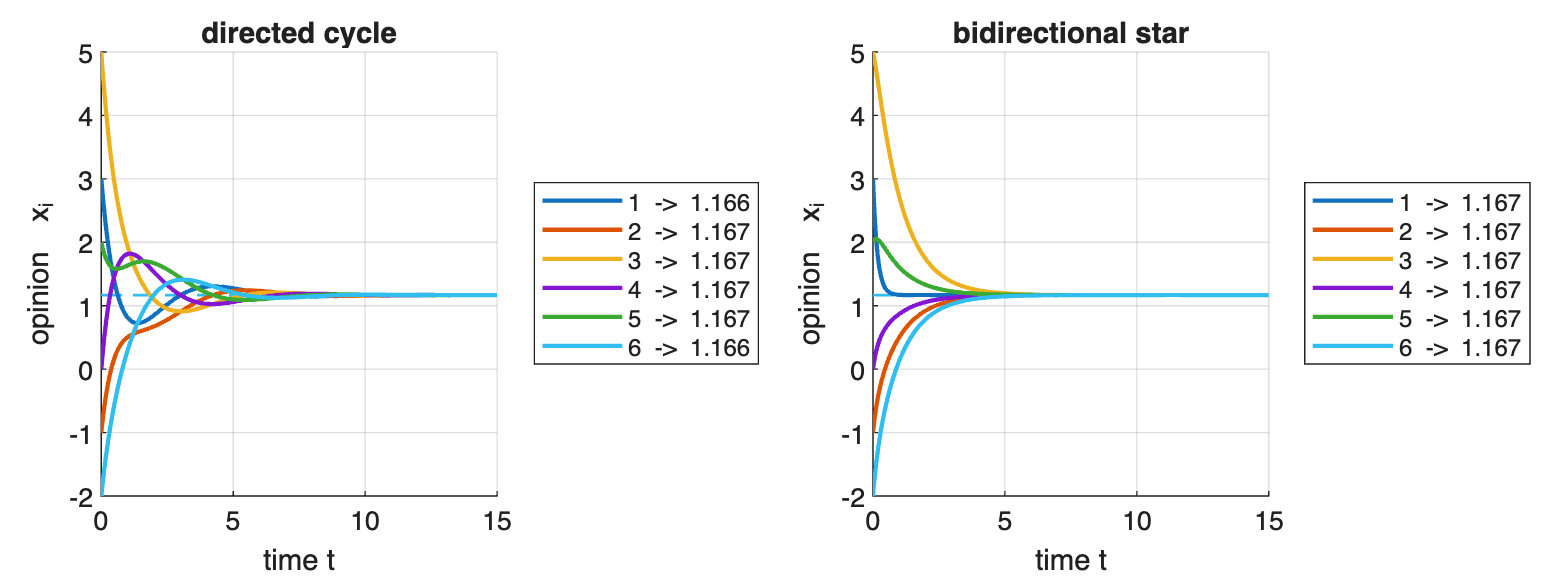

cases = {'directed cycle',     ring_graph(N); ...
         'bidirectional star', star_graph(N,'bidirectional')};

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:2
    p = laplacian_power(cases{k,2});
    X = sim_abelson(cases{k,2}, x0, t);
    nexttile;
    plot_opinions(X, t, 'Limit', (p.' * x0) * ones(N,1), ...
                  'Title', cases{k,1}, 'Subtitle','');
end

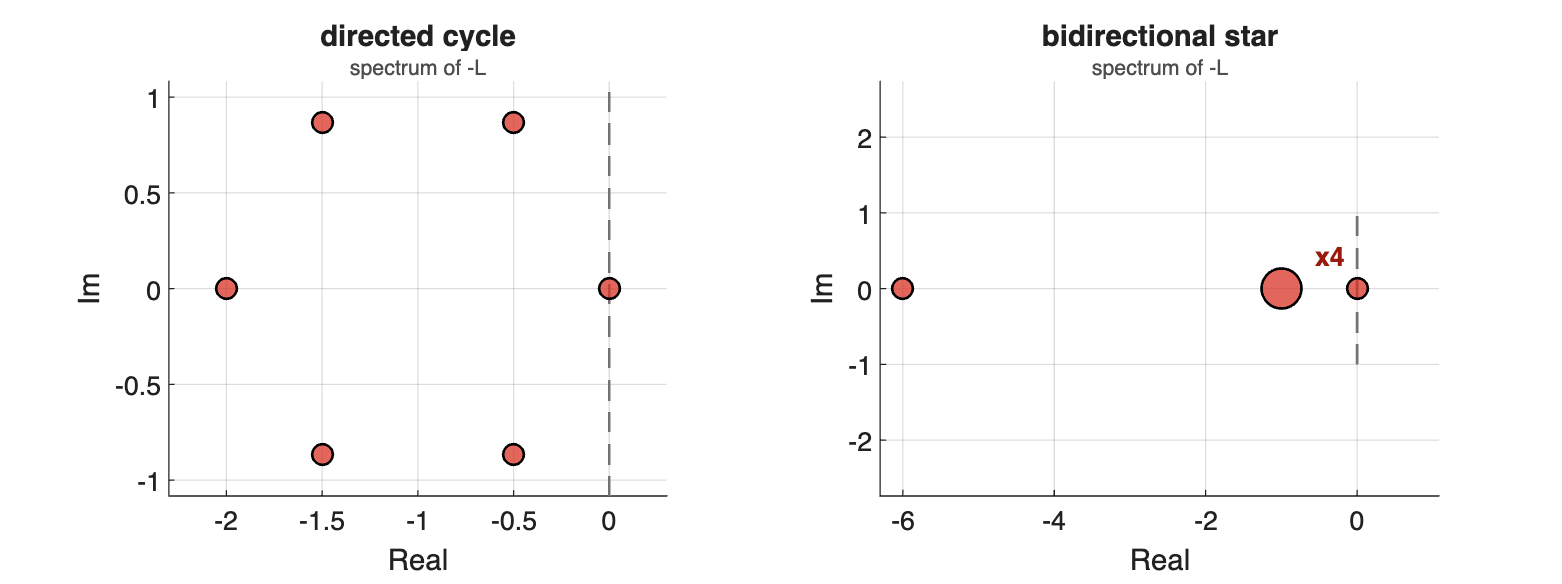

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:2
    nexttile;
    plot_eigenvalues(-laplacian(cases{k,2}), 'continuous', ...
        'Title', cases{k,1}, 'Subtitle','spectrum of -L');
end


for k = 1:2
    A   = cases{k,2};
    ev  = eig(laplacian(A));
    gap = min(real(ev(abs(ev) > 1e-9)));
    fprintf('%-20s DT period = %d   CT gap = %.4f   consensus = %.4f\n', ...
        cases{k,1}, graph_period(A), gap, laplacian_power(A).' * x0);
end

directed cycle       DT period = 6   CT gap = 0.5000   consensus = 1.1667
bidirectional star   DT period = 2   CT gap = 1.0000   consensus = 1.1667


One eigenvalue at the origin and every other one strictly in the left half-plane: e^{-Lt} converges for any non-negative A (Corollary 2.1). Both graphs are rooted, so both reach consensus (Theorem 2.1), and both are weight-balanced, so the limit is the plain average.

## 2.4.2 Self-loops are invisible to the Laplacian

In Chapter 1 the number of self-loops decided convergence and moved the whole spectrum. They cancel in L = diag(A1) - A.

base = ring_graph(N);
d = 0;
for m = 0:N
    Am = base + diag([ones(m,1); zeros(N-m,1)]);
    d  = max(d, norm(laplacian(Am) - laplacian(base), Inf));
end
fprintf('max ||L(A + D_self) - L(A)||  over m = 0 ... 6 :  %.3e\n', d);

max ||L(A + D_self) - L(A)||  over m = 0 ... 6 :  0.000e+00


The seven matrices that produced seven different spectra in section 1.5.3 share one Laplacian. This is why aperiodicity appears nowhere in the continuous-time criteria.

## 2.4.3 Row sums are free

A is not normalised: its row sums set how strongly each agent is pulled.

A = ring_graph(N) + ring_graph(N).';

figure('Position',[0 0 850 450]); hold on
for c = [0.5 1 2]
    X   = sim_abelson(c*A, x0, t);
    ev  = eig(laplacian(c*A));
    gap = min(real(ev(abs(ev) > 1e-9)));
    plot(t, max(X,[],1) - min(X,[],1), 'LineWidth', 1.7, ...
         'DisplayName', sprintf('c = %.1f,  gap = %.2f', c, gap));
    fprintf('c = %.1f : consensus value = %.4f\n', c, laplacian_power(c*A).' * x0);
end

c = 0.5 : consensus value = 1.1667
c = 1.0 : consensus value = 1.1667
c = 2.0 : consensus value = 1.1667


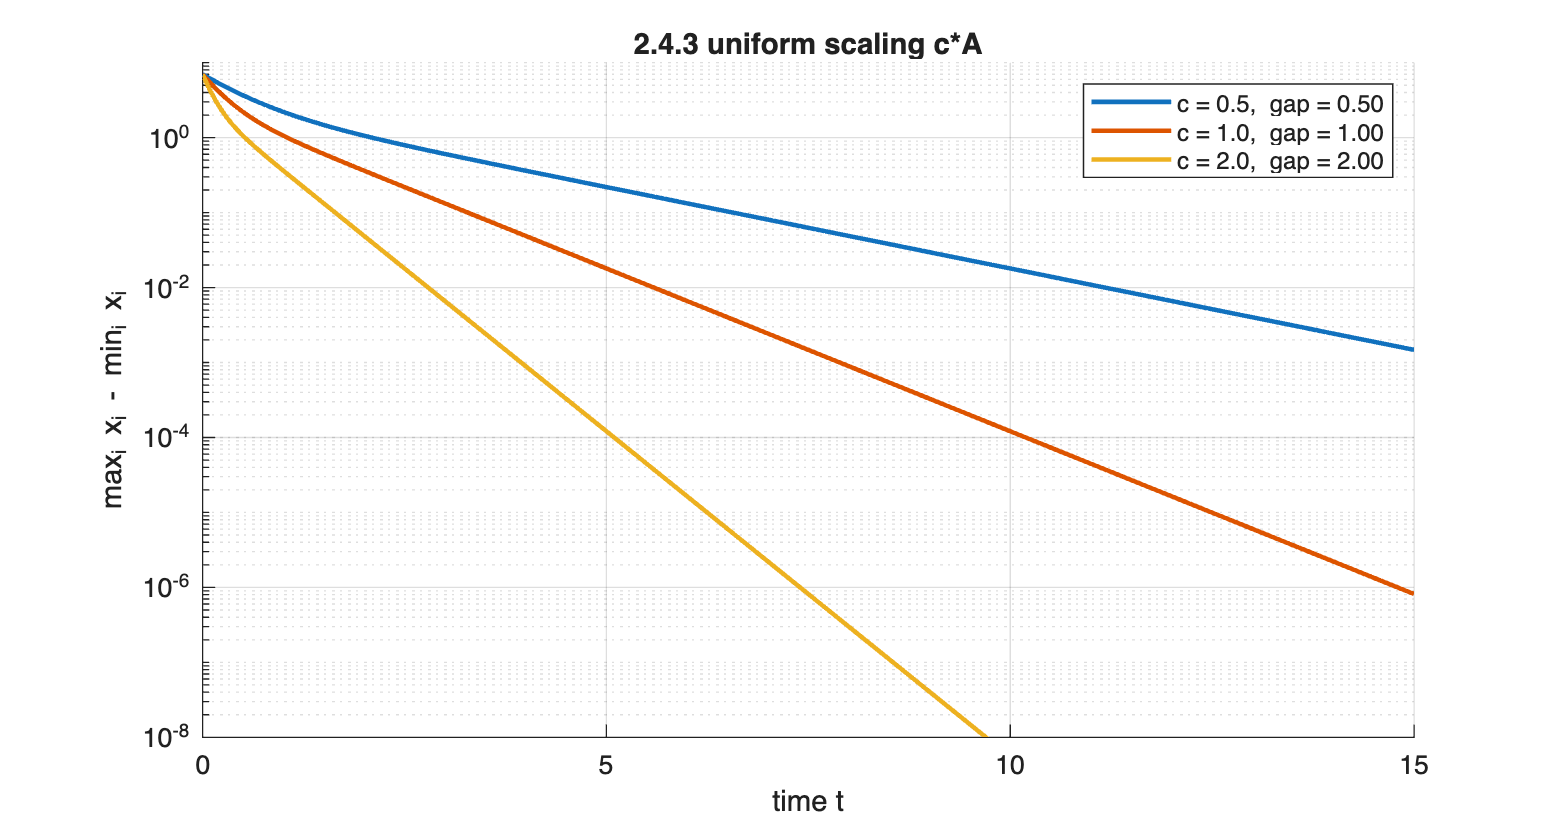

set(gca, 'YScale', 'log'); grid on; legend('Location','northeast');
xlabel('time t'); ylabel('max_i x_i - min_i x_i'); ylim([1e-8 10]);
title('2.4.3 uniform scaling c*A', 'FontWeight','bold');

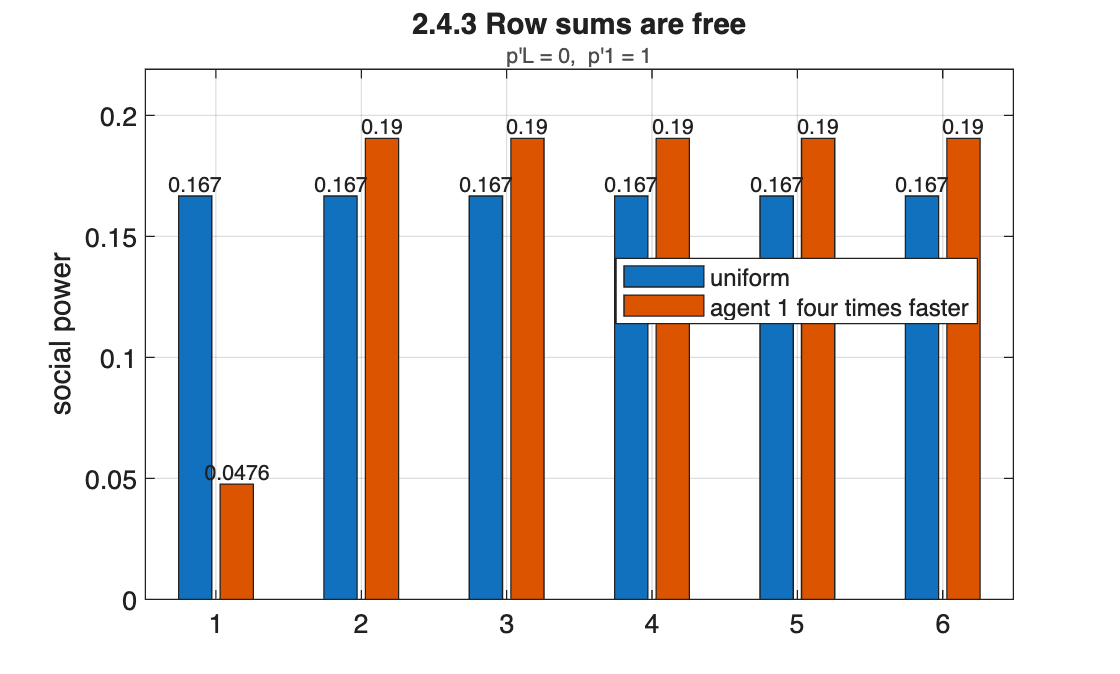

C1 = diag([4 1 1 1 1 1]);          % agent 1 responds four times faster
P  = [laplacian_power(A), laplacian_power(C1*A)];

figure;
plot_bars(P, [], 'Series', {'uniform', 'agent 1 four times faster'}, ...
    'YLabel','social power', 'Title','2.4.3 Row sums are free', ...
    'Subtitle','p''L = 0,  p''1 = 1')


fprintf('uniform          : p''x0 = %.4f\n', P(:,1).' * x0);

uniform          : p'x0 = 1.1667


fprintf('agent 1 faster   : p''x0 = %.4f\n', P(:,2).' * x0);

agent 1 faster   : p'x0 = 0.9048


Uniform scaling multiplies the gap by c and leaves the limit unchanged. Scaling one row replaces p by a vector proportional to C^{-1}p: the agent that responds faster ends up with less weight in the outcome. Neither effect can occur in discrete time, where every row is forced to sum to one.

## 2.4.4 Rootedness is the only condition

A zero row of A means xdot_i = 0, which is what section 2.3 calls a stubborn agent.

cases = {'out-star',            common_topology('star-out'); ...
         'two disjoint blocks', two_communities(N/2, N/2, 0)};

for k = 1:2
    laplacian_report(cases{k,2}, cases{k,1});
    fprintf('\n');
end

out-star   (6 agents, continuous time)
  strengths (row sums of A): [5 0 0 0 0 0]
  in-strengths (col sums)  : [0 1 1 1 1 1]   weight-balanced: no
  strong components : 6   closed: 5
  rooted: no    ->  converges, but NOT to consensus (one limit per closed component)
  eigenvalue 0 of L: multiplicity 5   spectral gap: 5.0000
  stubborn agents (zero rows of A): [2 3 4 5 6]
two disjoint blocks   (6 agents, continuous time)
  strengths (row sums of A): [2 2 2 2 2 2]
  in-strengths (col sums)  : [2 2 2 2 2 2]   weight-balanced: yes
  strong components : 2   closed: 2
  rooted: no    ->  converges, but NOT to consensus (one limit per closed component)
  eigenvalue 0 of L: multiplicity 2   spectral gap: 3.0000


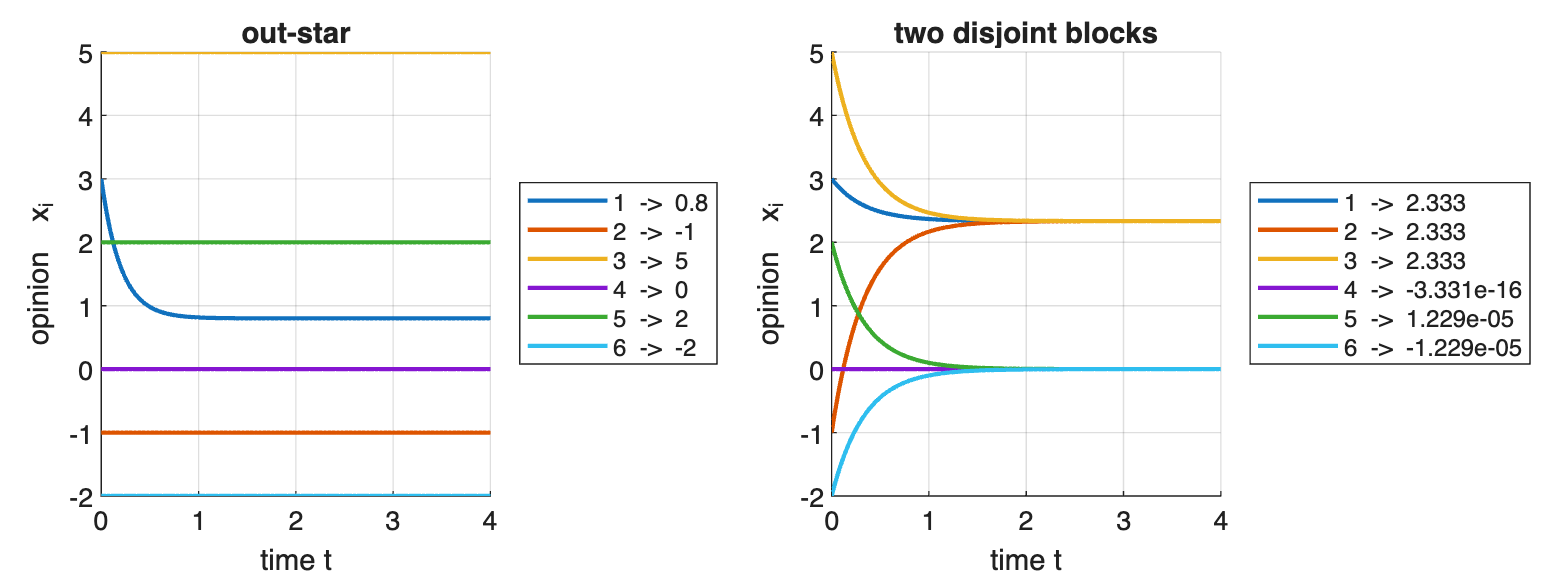

ts = linspace(0, 4, 300);

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:2
    nexttile;
    X = sim_abelson(cases{k,2}, x0, ts);
    plot_opinions(X, ts, 'Title', cases{k,1}, 'Subtitle','');
end

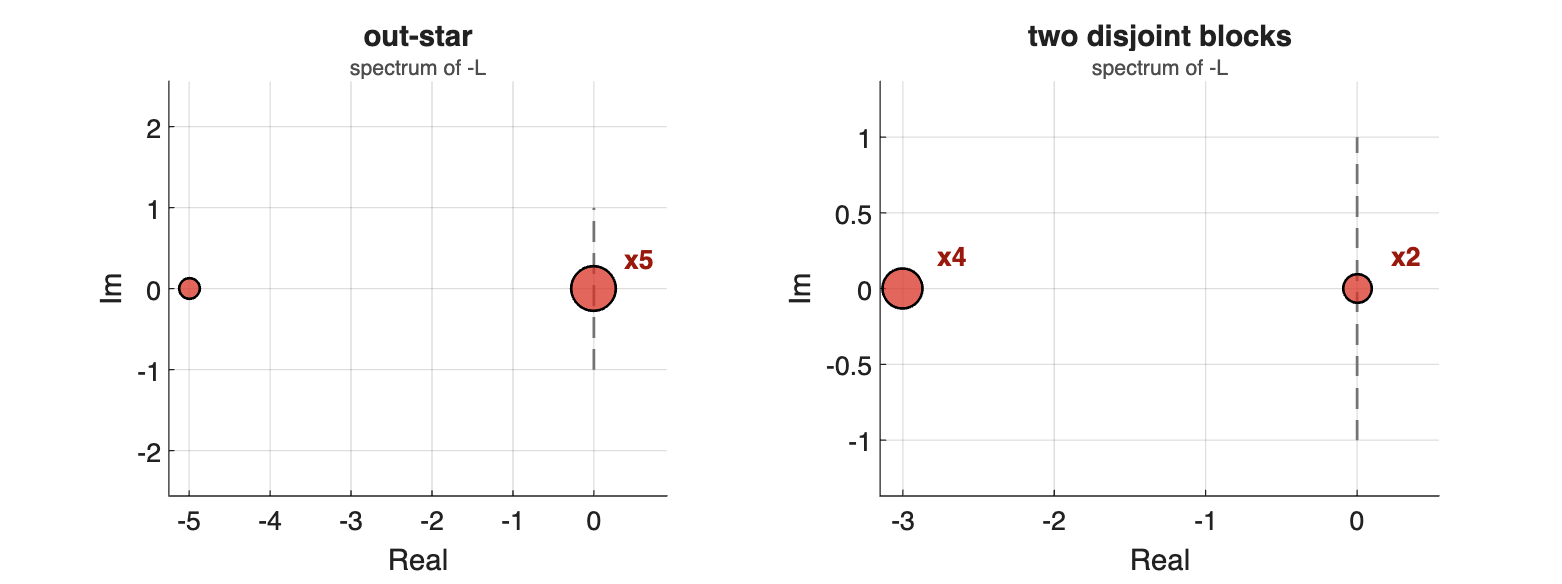


figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:2
    nexttile;
    plot_eigenvalues(-laplacian(cases{k,2}), 'continuous', ...
        'Title', cases{k,1}, 'Subtitle','spectrum of -L');
end

Both converge, neither reaches consensus. The multiplicity of the eigenvalue 0 counts the closed strong components, 5 and 2, exactly as the multiplicity of the eigenvalue 1 does in Chapter 1.

## 2.4.5 The spectral gap sets the rate

The gap is min Re(lambda) over the nonzero eigenvalues of L; for an undirected graph it is the Fiedler value.

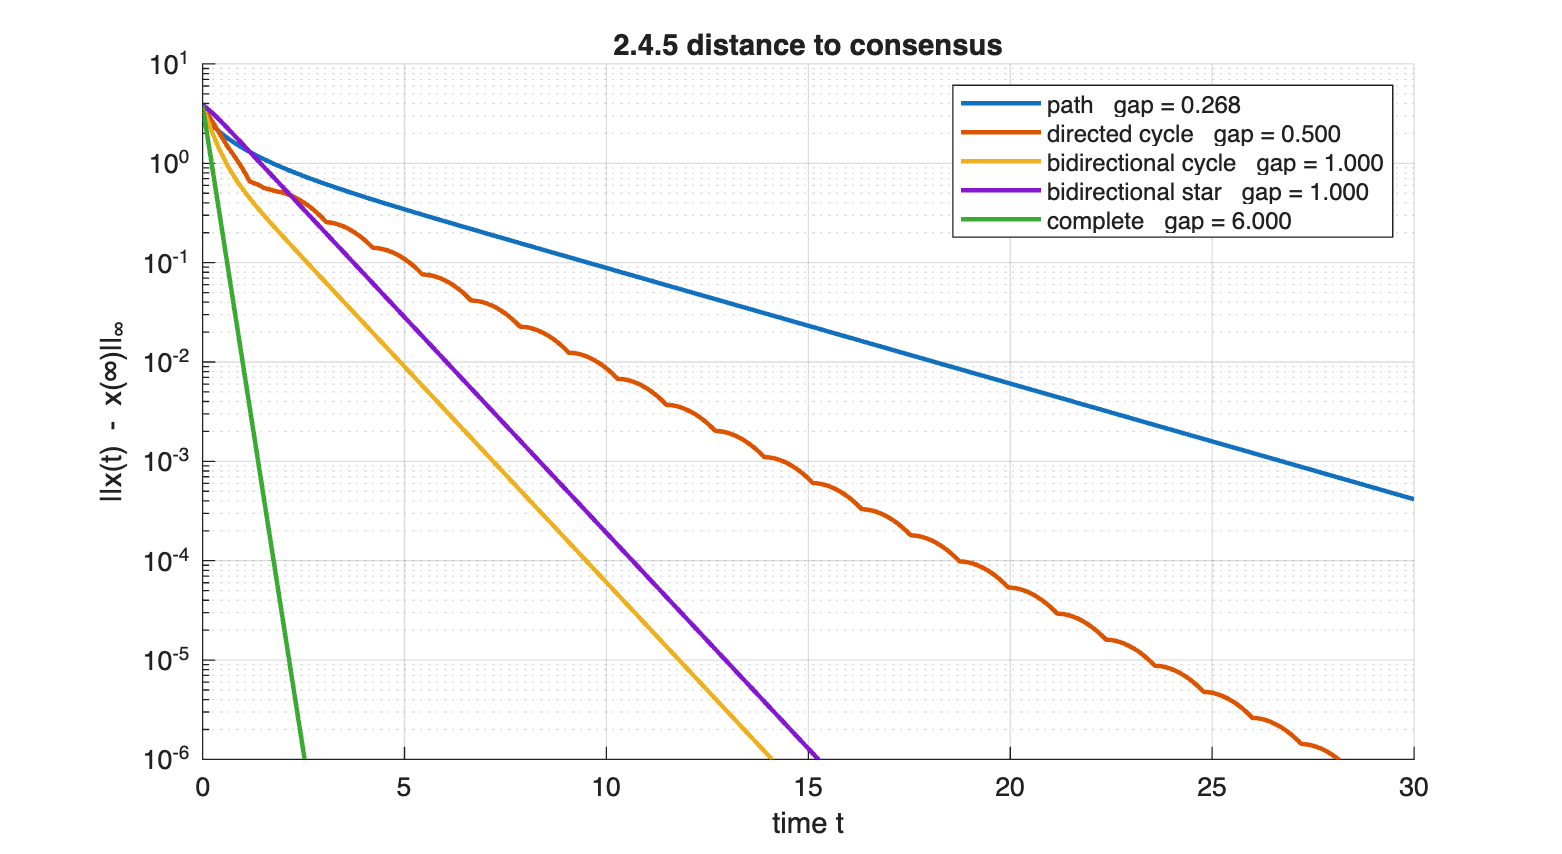

tops = {'path',                path_graph(N) + path_graph(N).'; ...
        'directed cycle',      ring_graph(N); ...
        'bidirectional cycle', ring_graph(N) + ring_graph(N).'; ...
        'bidirectional star',  star_graph(N,'bidirectional'); ...
        'complete',            complete_graph(N)};

tg   = linspace(0, 30, 900);
rows = cell(size(tops,1), 1);

figure('Position',[0 0 860 470]); hold on
for k = 1:size(tops,1)
    A    = tops{k,2};
    ev   = eig(laplacian(A));
    gap  = min(real(ev(abs(ev) > 1e-9)));
    X    = sim_abelson(A, x0, tg);
    dev  = max(abs(X - laplacian_power(A).' * x0), [], 1);
    plot(tg, dev, 'LineWidth', 1.7, ...
         'DisplayName', sprintf('%s   gap = %.3f', tops{k,1}, gap));
    j = find(dev < 1e-3, 1);
    rows{k} = {tops{k,1}, gap, tg(j), gap*tg(j)};
end
set(gca, 'YScale', 'log'); grid on; legend('Location','northeast');
xlabel('time t'); ylabel('||x(t) - x(\infty)||_\infty'); ylim([1e-6 10]);
title('2.4.5 distance to consensus', 'FontWeight','bold');


rate = cell2table(vertcat(rows{:}), ...
    'VariableNames', {'topology','gap','t_settle','gap_times_t'})

rate = 5×4 table
           topology              gap      t_settle    gap_times_t
    _______________________    _______    ________    ___________

    {'path'               }    0.26795      26.73       7.1622   
    {'directed cycle'     }        0.5     14.383       7.1913   
    {'bidirectional cycle'}          1      7.208        7.208   
    {'bidirectional star' }          1      8.376        8.376   
    {'complete'           }          6     1.4016       8.4093   


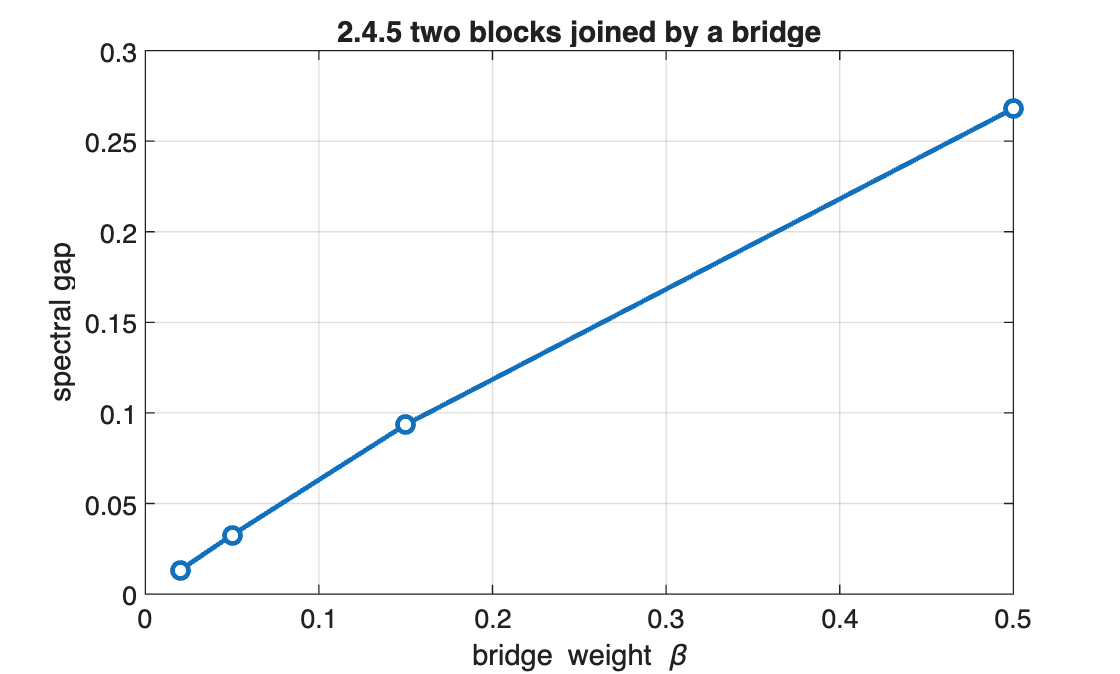

beta = [0.02 0.05 0.15 0.5];
gapb = zeros(size(beta));
for k = 1:numel(beta)
    ev = eig(laplacian(two_communities(N/2, N/2, beta(k))));
    gapb(k) = min(real(ev(abs(ev) > 1e-9)));
end

figure;
plot(beta, gapb, 'o-', 'LineWidth', 1.8, 'MarkerFaceColor','w'); grid on
xlabel('bridge weight \beta'); ylabel('spectral gap');
title('2.4.5 two blocks joined by a bridge', 'FontWeight','bold');

gap times t_settle is nearly constant across a 22-fold range of gaps. A weak bridge makes the gap small, which is the slow inter-block relaxation already seen in Chapter 1.

## 2.4.6 Sampling the flow

Lemma 2.1: e^{-L tau} is stochastic with positive diagonal entries.

A   = ring_graph(N);                 % period 6: never converges in discrete time
tau = 0.4;
W   = expm(-laplacian(A) * tau);

fprintf('row-stochastic: %d   min diagonal: %.4f   min entry: %.3e\n', ...
    is_row_stochastic(W), min(diag(W)), min(W(:)));

row-stochastic: 1   min diagonal: 0.6703   min entry: 5.720e-05



K  = 30;
Xd = sim_degroot(W, x0, K);
Xc = sim_abelson(A, x0, tau*(0:K));
fprintf('max |sim_degroot(e^{-L tau}) - sim_abelson| = %.3e\n', max(abs(Xd(:) - Xc(:))));

max |sim_degroot(e^{-L tau}) - sim_abelson| = 2.887e-15


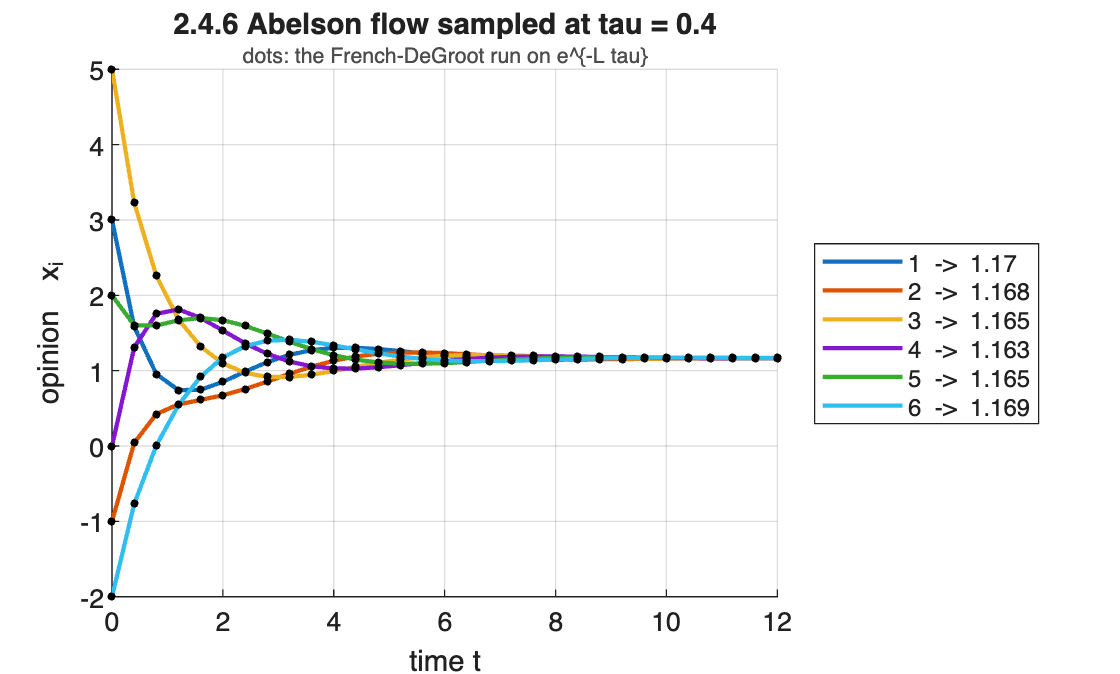


figure;
plot_opinions(Xc, tau*(0:K), 'Title','2.4.6 Abelson flow sampled at tau = 0.4', ...
    'Subtitle','dots: the French-DeGroot run on e^{-L tau}')
hold on
plot(tau*(0:K), Xd.', 'k.', 'MarkerSize', 9, 'HandleVisibility','off');
hold off

The directed cycle has period 6 and oscillates forever under French-DeGroot, yet the sampled flow converges: e^{-L tau} has a strictly positive diagonal, which is the hypothesis of Corollary 1.1.